# **IO134 - Analog Inputs and Digital Loopback**

This example demonstrates a simple communication between an external signal and 2 Analog inputs present on the IO134, without using DMA (Direct Memory Access), as well as the communication between two DIO pins.

The IO134 I/O module is a fast, simultaneous-sampling, 16-bit analog input module, complete with dedicated Simulink® driver blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO134 I/O module installed

- Connector cable from the I/O module to the terminal boards

- 2 50-pin terminal boards with jumper wires

- An external Signal source

### Test Setup

On the terminal boards of the analog I/O module, connect the positive (+) pins of the Analog Input 1 and 2 to an external signal and the negative (-) pins of the Analog Input 1 and 2 both to GND of the external signal. Alternatively, you can also use a differential external signal. In that case, connect the negative (-) output of the external signal source to the negative pins of Analog input 1 and 2. Finally, connect DIO 1 and DIO 5.

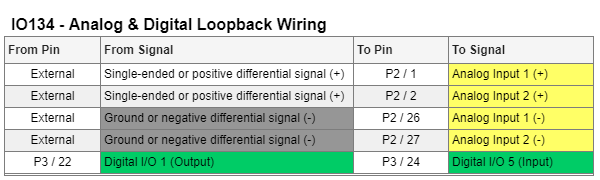

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO134_AnalogInputsDigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the IO134 Setup, Analog Input, Digital Input and Digital Output blocks. Analog Input 1 and 2 as well as Digital IO 1 and 5 are enabled in the Setup Block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scope connected to the [IO134 Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io134_analog_input_v2)  block and check if the signals displayed correspond to the signals created by the external signal generator. Two signals must be displayed. The screenshot below is an example of two sine wave signals with different phase shifts. 

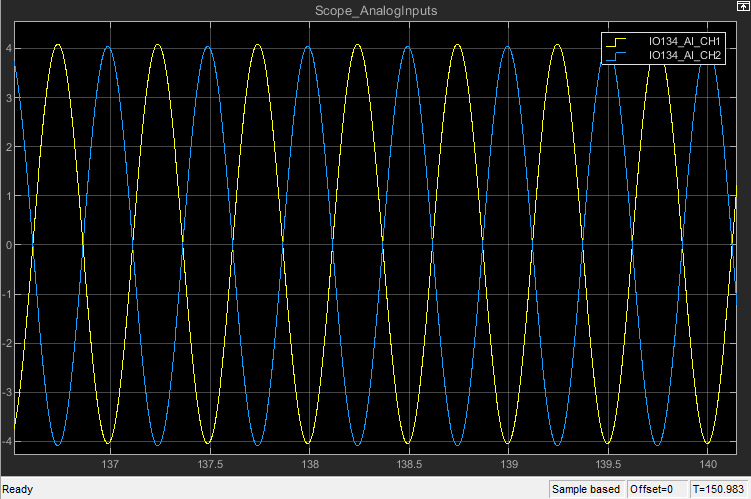

Open the Simulink scope connected to the [IO134 Digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io134_digital_input_v2)  block and check if the signal displayed correspond to the signal created by the pulse block in the model:

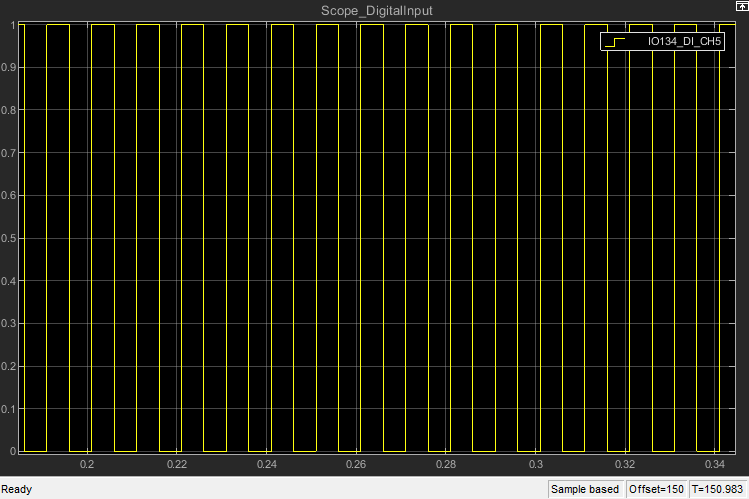

## Additional References

- [IO134 examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io134_examples)

- [IO134 documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io134)